## **JULIO CESAR GARCIA RIBEIRO                                    RA: 1994484**

### **ATIVIDADE PRÁTICA 3**

Primeiramente, se definiu a função de transferência do circuito RLC e foi discretizado nos métodos pedidos.

s = tf('s');
tf_c = 1/(58.89e-9*s^2 + 94e-6*s + 1)

tf_c =
 
                1
  -----------------------------
  5.889e-08 s^2 + 9.4e-05 s + 1
 
Continuous-time transfer function.



Função de transferência da planta.

tf_c_closed = tf_c/(1+tf_c)

tf_c_closed =
 
                  5.889e-08 s^2 + 9.4e-05 s + 1
  --------------------------------------------------------------
  3.468e-15 s^4 + 1.107e-11 s^3 + 1.855e-07 s^2 + 0.000282 s + 2
 
Continuous-time transfer function.



Função de transferência de malha fechada da planta.

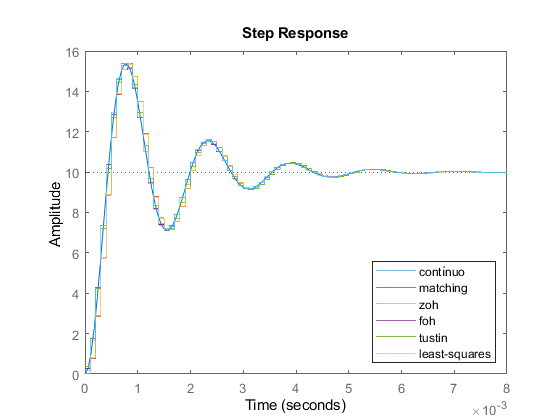

T_sample = 1/10000;
tf_d_m = c2d(tf_c, T_sample, 'matched');
tf_d_zoh = c2d(tf_c, T_sample, 'zoh');
tf_d_foh = c2d(tf_c, T_sample, 'foh');
tf_d_tustin = c2d(tf_c, T_sample, 'tustin');
tf_d_ls = c2d(tf_c, T_sample, 'least-squares');
step(10*tf_c, 10*tf_d_m, 10*tf_d_zoh, 10*tf_d_foh, 10*tf_d_tustin, 10*tf_d_ls);
legend('contínuo', 'matching', 'zoh', 'foh', 'tustin', 'least-squares', 'Location', 'southeast');

Gráfico contendo a resposta temporal de malha aberta dos sistemas discretizados e do sistema contínuo.

Foi plotada a resposta em frequencia do sistema contínuo e dos sistemas discretizados.

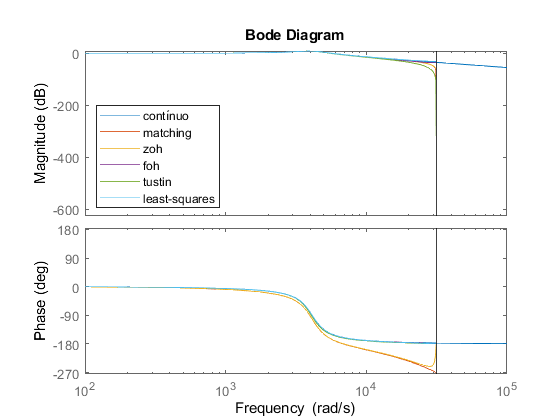

bode(tf_c, tf_d_m, tf_d_zoh, tf_d_foh, tf_d_tustin, tf_d_ls);
axes_handles = findall(gcf, 'type', 'axes');
legend(axes_handles(3), 'contínuo', 'matching', 'zoh', 'foh', 'tustin', 'least-squares', 'Location', 'southwest');

Diagrama de bode dos sistemas discretizados e contínuo.

Se projetou um compensador para ajustar transitório e o erro de regime permanente foi zerado utilizando um integrador. Foi utilizado o método da bissetriz para calcular a localização do polo e do zero do compensador avanço de fase. Mais detalhes abaixo.

Beta é encontrado pela relação do polo dominante calculado pelas especificações de desempenho, phi é a deficiência angular, alpha e T são utilizados para calcualar a posição do polo e do zero.

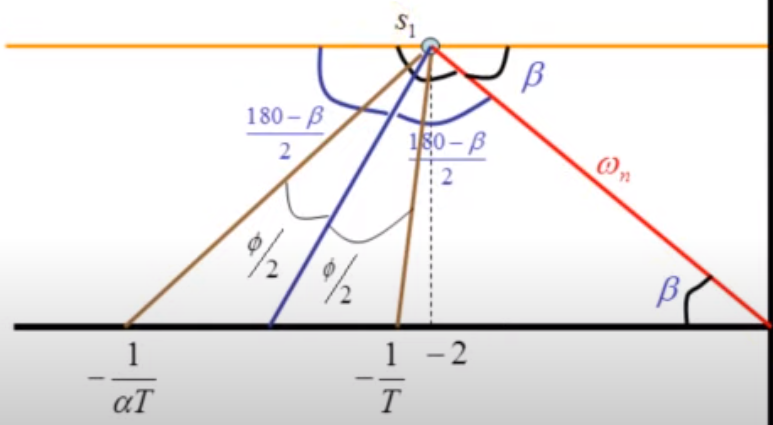

Com este método se chega na resposta abaixo.

% Calculo dos parâmetros do compensador lead
tf_c_int = tf_c/s;  % Adicionado um integrador
Mp = 10;
Ts = 0.03;
qsi = log(Mp/100)/sqrt(pi^2+log(Mp/100)^2);
Wn = 4/(qsi*Ts);
pole = -1*(qsi*Wn)-1i*(Wn*sqrt(1-qsi*qsi));
phi = 180-rad2deg(angle(evalfr(tf_c_int, pole)));
beta = abs(atand(imag(pole)/real(pole)));
T = abs(sind((180-beta+phi)/2)/(Wn*sind((180-beta-phi)/2)));
alpha = abs(sind((180-beta-phi)/2)/(Wn*T*sind((180-beta+phi)/2)));
Gc = alpha*(T*s + 1)/(alpha*T*s + 1);
Kc = 1/abs(evalfr(Gc*tf_c_int/(1+(Gc*tf_c_int)), pole));
Gc = Kc*Gc

Gc =
 
  0.9792 s + 370
  --------------
  0.007427 s + 1
 
Continuous-time transfer function.



Função de transferência do compensador.

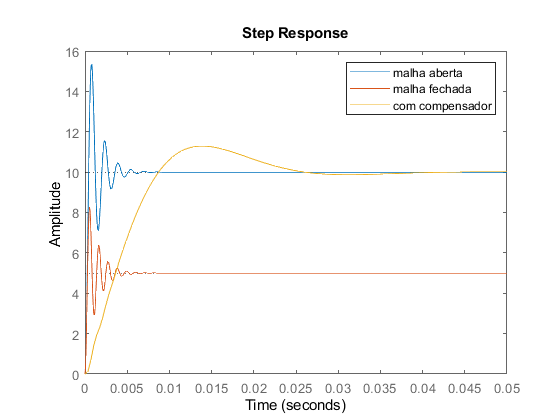

% Comparação do sistema em malha aberta, malha fechada e com compensador discretizado com Fs = 10kHz
GcGs_open = Gc*tf_c_int;
GcGs_closed = GcGs_open/(1+(GcGs_open));
step(10*tf_c, 10*tf_c_closed, 10*GcGs_closed);
legend('malha aberta', 'malha fechada', 'com compensador');

Se percebe um aumento grande no tempo de estabelecimento do sistema, mas o potencial de overshoot diminuiu consideravelmente. Quando se usa um compesandor lead sem o integrador são encontrados tempos de estabelecimento menores que o da planta em malha aberta, mas o overshoot é muito grande, o que pode impossibilitar a implantação do controlador no microcontrolador, pois a ação de controle seria muito grande.

A respostas foi discretizada e pode ser observada abaixo.

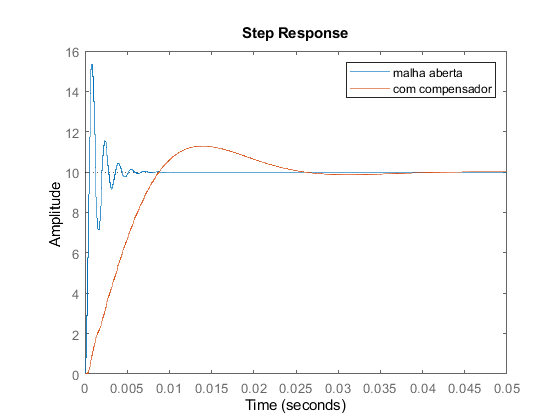

% Comparação do sistema em malha aberta e malha fechada com compensador discretizado com Fs = 10kHz
GcGs_closed_d = c2d(GcGs_closed, T_sample, 'zoh');
step(10*tf_d_zoh, 10*GcGs_closed_d);
legend('malha aberta', 'com compensador');

Resposta ao impulso discretizada dos sistemas em malha aberta, fechada e com compensador lead.

O sistema construido com coversor AD DA em cascata pode ser observado abaixo.

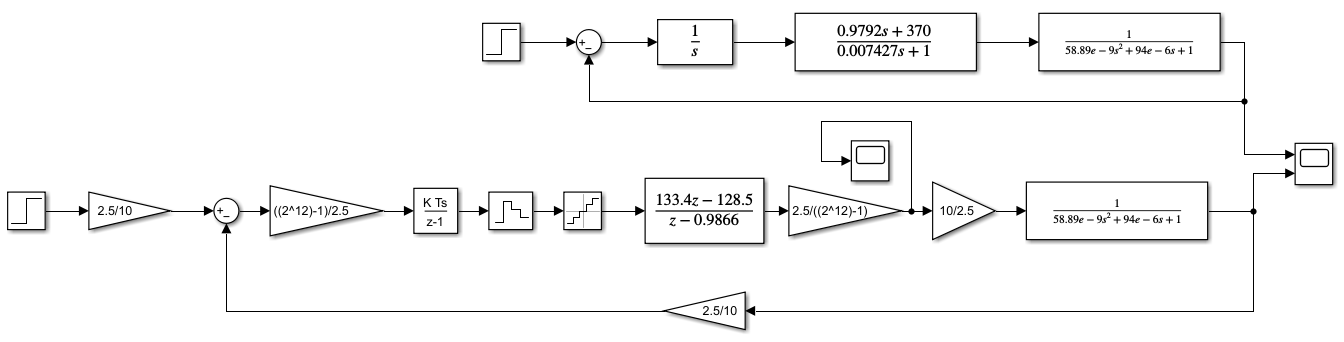

As saídas obtidas nos scopes podem ser observadas abaixo.

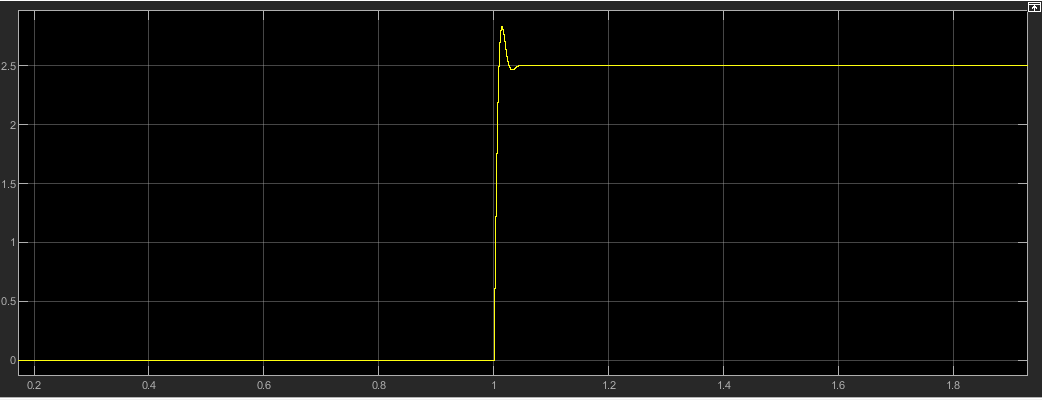

Saída da ação de controle. Menor que 3.3V (especificação do microcontrolador).

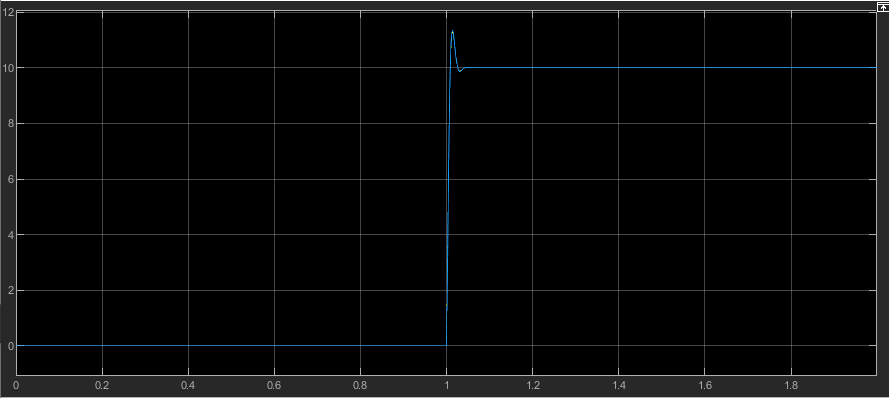

Saída do sistema controlado quantizado (amarelo) e contínuo (azul).

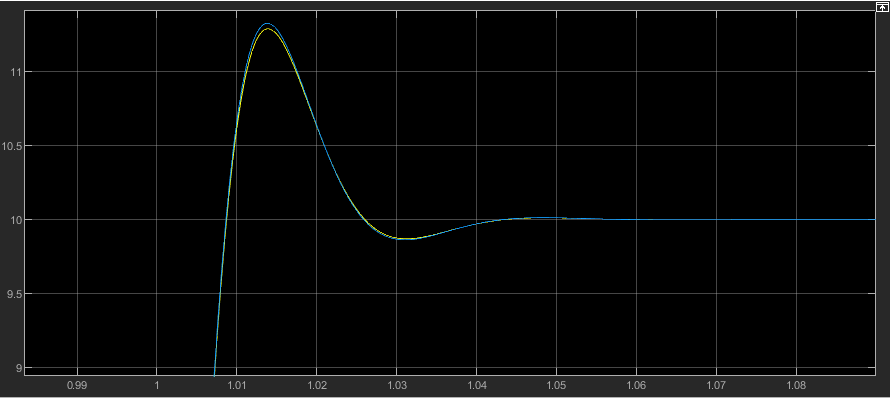

Saída do sistema controlado quantizado (amarelo) e contínuo (azul). Se percebe muita semelhança entre os sinais.

Para se calcular a expressão da ação de controle que será embarcada, primeiramente se fez a conversão da expressão do controlador utilizando o método tustin.

c2d(Gc, T_sample, 'tustin')

ans =
 
  133.4 z - 128.5
  ---------------
    z - 0.9866
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



Então, é calculado da seguinte forma:


$$\frac{U\left(z\right)}{E\left(z\right)}=\frac{133\ldotp 4z-128\ldotp 5}{\;z-0\ldotp 9866}*\frac{\mathrm{Ts}}{z-1}*\frac{z^{-2} }{\;z^{-2} }$$



$$\frac{U\left(z\right)}{E\left(z\right)}=\frac{133\ldotp 4z\textrm{Ts}-128\ldotp 5\textrm{Ts}}{\;z^2 -1\ldotp 9866z+0\ldotp 9866}*\frac{z^{-2} }{\;z^{-2} }$$



$$\frac{U\left(z\right)}{E\left(z\right)}=\frac{133\ldotp 4z^{-1} \textrm{Ts}-128\ldotp 5z^{-2} \textrm{Ts}}{\;1-1\ldotp 9866z^{-1} +0\ldotp 9866z^{-2} }*\frac{z^{-2} }{\;z^{-2} }$$



$$u\left(k\right)=1\ldotp 9866u\left(k-1\right)-0\ldotp 9866u\left(k-2\right)+133\ldotp 4\mathrm{Ts}e\left(k-1\right)-128\ldotp 5\mathrm{Ts}e\left(k-2\right)$$


Essa expressão é valida para taxas de amostragem Fs = 10kHz.